clear;clc;clf;
% Data from 5/30/2023 - Forresti
format short g ; format compact 
folder_path = "/Users/nbonnie/MATLAB/stereo-calibration-free-firefly";
addpath(genpath(folder_path))
addpath(genpath(strcat(folder_path,"/control")))
fnames = dir(strcat(folder_path,"/control/*.mat"))

fnames = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum

data1 = load(strcat(folder_path, "/control/", fnames(1).name));
data2 = load(strcat(folder_path, "/control/", fnames(2).name));
fns1 = fieldnames(data1);
fns2 = fieldnames(data2);

df1 = data1.(fns1{1}).xyt;
df2 = data2.(fns2{1}).xyt;
c1n = data1.(fns1{1}).n;
c2n = data2.(fns2{1}).n;

frame_width = data1.(fns1{1}).mov.Width;
frame_height = data1.(fns1{1}).mov.Height;

% Clean out noise and persistent objects:
df1 = removePersistentObjects(df1);
df2 = removePersistentObjects(df2);

% FOR CONTROL TRIM ONLY
c1_start = 104;
c2_start = 434;
dk = c2_start - c1_start;

% Find all 1-flash-frames to calibrate on:
[calTraj, id1, id2] = extractCalibrationTrajectoriesDebug(df1,df2,dk);

% TODO: Create saved data folder in dir
%
%
% stereoParams = importdata(strcat(fns1{1},"--",fns2{1},".mat"))
% disp(strcat('Fundamental matrix already exists for these files, loading:',strcat(fns1{1},"--",fns2{1},".mat")))

% Auto-generated by stereoCalibrator app on 13-Dec-2023
%-------------------------------------------------------


% Define images to process
imageFileNames1 = {'/Users/nbonnie/Desktop/stereo_controlled_data/cal1/13.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/14.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/19.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/21.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/22.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/23.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/24.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/26.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/27.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/29.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/3.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/5.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/6.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/7.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/8.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal1/9.bmp',...
    };
imageFileNames2 = {'/Users/nbonnie/Desktop/stereo_controlled_data/cal2/13.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/14.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/19.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/21.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/22.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/23.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/24.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/26.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/27.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/29.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/3.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/5.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/6.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/7.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/8.bmp',...
    '/Users/nbonnie/Desktop/stereo_controlled_data/cal2/9.bmp',...
    };

% Detect calibration pattern in images
detector = vision.calibration.stereo.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames1, imageFileNames2);


% Generate world coordinates for the planar patten keypoints
squareSize = 215.9;  % in units of 'millimeters' (8.5in)
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Read one of the images from the first stereo pair
I1 = imread(imageFileNames1{1});
[mrows, ncols, ~] = size(I1);

% Calibrate the camera
[stereoParams, pairsUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

fprintf('Beginning point matching and triangulation...\nStart time: %s\n',datetime('now'))

Beginning point matching and triangulation...
Start time: 08-Feb-2024 21:36:13


% Finds matching points frame by frame after applying t and R
[matched_points_1,matched_points_2,metadata]=matchStereo(df1, df2, stereoParams, dk);

Using real stereoParams object


% Triangulate
% xyzt = triangulateStereo(matched_points_1, matched_points_2, stereoParams);
% successRate = size(xyzt,1)/min(size(df1,1),size(df2,1));
% fprintf('Matching and triangulation completed with success rate: %.3f\nEnd time: %s\n',successRate,datetime('now'))

xyz = triangulate(calTraj.j1(:,1:2),calTraj.j2(:,1:2), stereoParams);

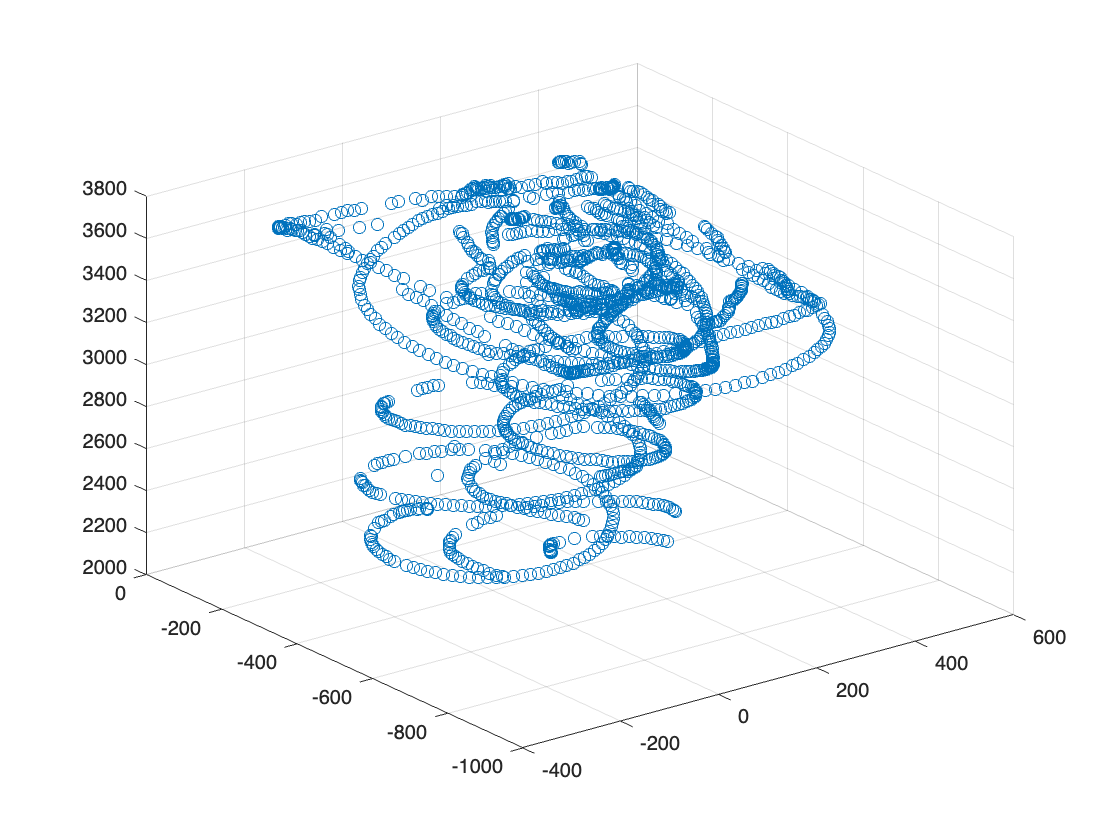

% Plot reconstruction
figure()
scatter3( xyz(:,1) , xyz(:,2) , xyz(:,3) , 37)